% Demo 5 - Run a full simulation with X amount o light emitters and Y
% photodiodes light receivers. In a sphere shape

% Starting with 4 light emitters and 12 photodiodes and moving around the
% sensor to get a received power in a grid of 0.5m of distance. I will need
% to do this 4 times each with only one light emitter turned on.


## Prepare the workspace

clear all;
close all;

% add the path to the projective geometry function 
addpath('../projgeom/');


## Prepare the Light Emitters (4)


%Emitters
n_Emitters = 2;
Pt = 1;
% Ps = 0.0025;
m = 4;


## Prepare the Photodiode Receiveis (12)


% Receivers
Np = 3;                 % Number of parallels in the sensor
Nm = 4;                 % Number of meridians in the sensor
n_Receivers = Np*Nm;    % Number of receivers
Ar = 0.01;              % Active receiving area
Ts = 1;                 % Optical filter gain
n = 1;                  % Receiver's internal refractive index
Psi = pi/2;             % Hemi-Fov
R = 1;                  % Receiver's responsivity


## Create and Populate data structures


% Create the emitters array:
Emitters = newEmitters(n_Emitters,Pt,Pt,m);

% Create the receiver structure:
Receivers = newReceivers(n_Receivers,Ar, Ts, n, Psi, R);


## Place Emitters and Receivers in 3D Space (3mx3mx2m)

% Considering a room with 3mx3mx2m (WxLxH).

% Emitters are placed at the ceiling, looking down and in a circle of
% radius=0.5m

Em_Base_HTM = Trans3(1.5,1.5,2)*RotX3(pi);      % Base HTM at the center of the ceiling. 

Emitters(1).HTM = Em_Base_HTM*Trans3(0.5,0,0);
Emitters(2).HTM = Em_Base_HTM*Trans3(0.5,0,5);
% Emitters(3).HTM = Em_Base_HTM*RotZ3(pi)*Trans3(0.5,0,0);
% Emitters(4).HTM = Em_Base_HTM*RotZ3(3*pi/2)*Trans3(0.5,0,0);

% Receivers are organized in Parallel and Meridians arragement of photo
% detectors, with Nm Meridians and 3 Parallels, in a sphere with
% radius=0.25
PDSensor = vlpCreateSensorParMer(Receivers, Np, Nm, 0.25);

% The sensor is initially placed at point (X,Y) = (0.5,3)
PDSensor = vlpMoveSensor(PDSensor,Trans3(0,3,0));


## Compute A, B and F matrices

A = Receiver2A(PDSensor);
B = Emitter2B(Emitters);
F = EmitRec2F(Emitters, PDSensor);


## Compute the received power

Pt_v = [Emitters.Pb]';
Pr = A*F*B*Pt_v;

% Get the max value. It will be used for scaling the received power
% graphics
MaxPr0 = max(Pr);

% Update the PDSensor received power
for i=1:numel(PDSensor)
    PDSensor(i).Pr = Pr(i);
end

k = 0.2;


## Plot Emitters and receivers

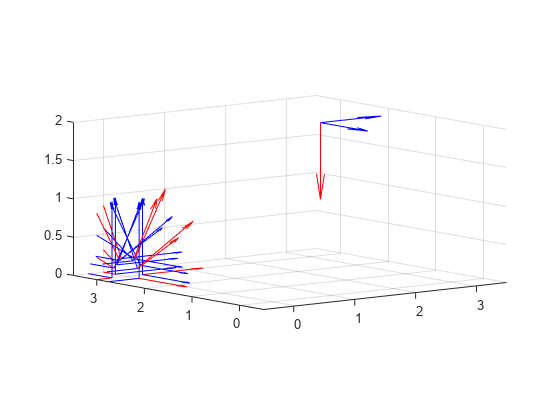


% Plot the emitters and receivers position
if(isgraphics(1))
    clf(1)
else
    figure(1)
end
figure(1)
PlotHTMArray(Emitters);
PlotHTMArray(PDSensor);
view(3)
axis 'equal'
axis([-0.5 3.5 -0.5 3.5 0 2])
grid on
% Adjust the point of view
view(-38,8);

## Animate plot (Light Emitter 1)

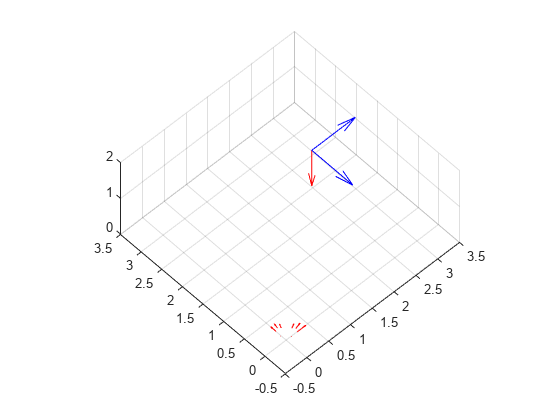


% Move the sensor, compute new received power and plot received power
% intensity

myArray = zeros(420, 8 * 12);

% Plot with received power intensity
if(isgraphics(2))
    clf(2)
else
    figure(2)
end
figure(2)
PlotHTMArray(Emitters);
hx = PlotHTMArrayPr(PDSensor,k);
view(3)
axis 'equal'
axis([-0.5 3.5 -0.5 3.5 0 2])
grid on
view([-43.35 53.33]);

for lane = 1:16
    if (lane == 1)
    else
        PDSensor = vlpMoveSensor(PDSensor,Trans3(0,-0.2,0));
    end
    for position=1:16
        if (position == 1)

        elseif (mod(lane,2))
            PDSensor = vlpMoveSensor(PDSensor,Trans3(0.2,0,0));
        else 
            PDSensor = vlpMoveSensor(PDSensor,Trans3(-0.2,0,0));
        end
        % Recompute the F matrix
        F = EmitRec2F(Emitters, PDSensor);
        
        % Compute received power
        Pt_v = [Emitters.Pb]';
        Pr = A*F*B*Pt_v;
    
        % Get the new max valuefor scaling the received power plot
        MaxPr = max(Pr);
    
        % Update the PDSensor received power
        for i=1:numel(PDSensor)
            PDSensor(i).Pr = Pr(i);
            position_number = lane * position;
            myArray(position_number, i) = Pr(i);
        end

        pause(.1)
        figure(2)
        delete(hx)
        % Plot the receiver power intensities, scaled
        hx = PlotHTMArrayPr(PDSensor,k*MaxPr/MaxPr0);
    
    end
end

hold off;

## Animate plot (Light Emitter 2)


% Move the sensor, compute new received power and plot received power
% intensity
Emitters = newEmitters(n_Emitters,Pt,Pt,m);
Emitters(1).HTM = Em_Base_HTM*RotZ3(pi/2)*Trans3(0.5,0,0);
Emitters(2).HTM = Em_Base_HTM*Trans3(0.5,0,5);

PDSensor = vlpMoveSensor(PDSensor,Trans3(0,3,0));

A = Receiver2A(PDSensor);
B = Emitter2B(Emitters);
F = EmitRec2F(Emitters, PDSensor);

% Plot with received power intensity
figure(42)
PlotHTMArray(Emitters);
hx = PlotHTMArrayPr(PDSensor,k);
view(3)
axis 'equal'
axis([-0.5 3.5 -0.5 3.5 0 2])
grid on
view([-43.35 53.33]);

for lane = 1:16
    if (lane == 1)
    else
        PDSensor = vlpMoveSensor(PDSensor,Trans3(0,-0.2,0));
    end
    for position=1:16
        if (position == 1)
            
        elseif (mod(lane,2))
            PDSensor = vlpMoveSensor(PDSensor,Trans3(0.2,0,0));
        else 
            PDSensor = vlpMoveSensor(PDSensor,Trans3(-0.2,0,0));
        end
        % Recompute the F matrix
        F = EmitRec2F(Emitters, PDSensor);
        
        % Compute received power
        Pt_v = [Emitters.Pb]';
        Pr = A*F*B*Pt_v;
    
        % Get the new max valuefor scaling the received power plot
        MaxPr = max(Pr);
    
        % Update the PDSensor received power
        for i=1:numel(PDSensor)
            PDSensor(i).Pr = Pr(i);
            position_number = lane * position;
            myArray(position_number, 1 * 12 + i) = Pr(i);
        end

        pause(.1)
        figure(42)
        delete(hx)
        % Plot the receiver power intensities, scaled
        hx = PlotHTMArrayPr(PDSensor,k*MaxPr/MaxPr0);
    
    end
end


## Animate plot (Light Emitter 3)

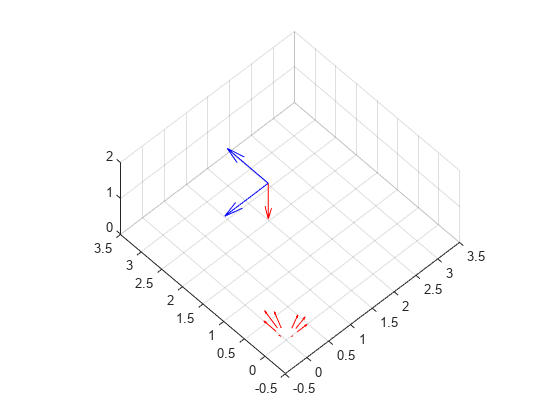


% Move the sensor, compute new received power and plot received power
% intensity
Emitters = newEmitters(n_Emitters,Pt,Pt,m);
Emitters(1).HTM = Em_Base_HTM*RotZ3(pi)*Trans3(0.5,0,0);
Emitters(2).HTM = Em_Base_HTM*Trans3(0.5,0,5);

PDSensor = vlpMoveSensor(PDSensor,Trans3(0,3,0));

A = Receiver2A(PDSensor);
B = Emitter2B(Emitters);
F = EmitRec2F(Emitters, PDSensor);

% Plot with received power intensity
figure(62)
PlotHTMArray(Emitters);
hx = PlotHTMArrayPr(PDSensor,k);
view(3)
axis 'equal'
axis([-0.5 3.5 -0.5 3.5 0 2])
grid on
view([-43.35 53.33]);

for lane = 1:16
    if (lane == 1)
    else
        PDSensor = vlpMoveSensor(PDSensor,Trans3(0,-0.2,0));
    end
    for position=1:16
        if (position == 1)
            
        elseif (mod(lane,2))
            PDSensor = vlpMoveSensor(PDSensor,Trans3(0.2,0,0));
        else 
            PDSensor = vlpMoveSensor(PDSensor,Trans3(-0.2,0,0));
        end
        % Recompute the F matrix
        F = EmitRec2F(Emitters, PDSensor);
        
        % Compute received power
        Pt_v = [Emitters.Pb]';
        Pr = A*F*B*Pt_v;
    
        % Get the new max valuefor scaling the received power plot
        MaxPr = max(Pr);
    
        % Update the PDSensor received power
        for i=1:numel(PDSensor)
            PDSensor(i).Pr = Pr(i);
            position_number = lane * position;
            myArray(position_number, 2 * 12 + i) = Pr(i);
        end

        pause(.1)
        figure(62)
        delete(hx)
        % Plot the receiver power intensities, scaled
        hx = PlotHTMArrayPr(PDSensor,k*MaxPr/MaxPr0);
    
    end
end

## Animate plot (Light Emitter 4)

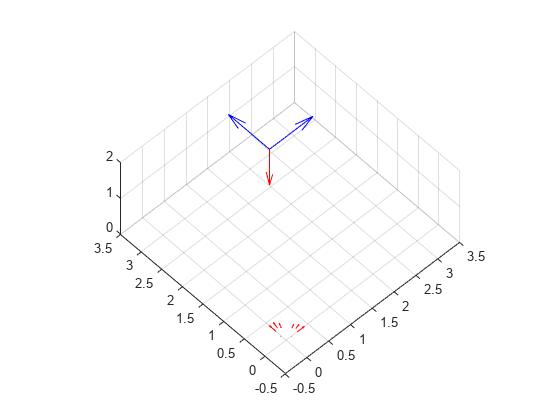


% Move the sensor, compute new received power and plot received power
% intensity
Emitters = newEmitters(n_Emitters,Pt,Pt,m);
Emitters(1).HTM = Em_Base_HTM*RotZ3(3*pi/2)*Trans3(0.5,0,0);
Emitters(2).HTM = Em_Base_HTM*Trans3(0.5,0,5);

PDSensor = vlpMoveSensor(PDSensor,Trans3(0,3,0));

A = Receiver2A(PDSensor);
B = Emitter2B(Emitters);
F = EmitRec2F(Emitters, PDSensor);
  
% Plot with received power intensity
figure(82)
PlotHTMArray(Emitters);
hx = PlotHTMArrayPr(PDSensor,k);
view(3)
axis 'equal'
axis([-0.5 3.5 -0.5 3.5 0 2])
grid on
view([-43.35 53.33]);

for lane = 1:16
    if (lane == 1)
    else
        PDSensor = vlpMoveSensor(PDSensor,Trans3(0,-0.2,0));
    end
    for position=1:16
        if (position == 1)
            
        elseif (mod(lane,2))
            PDSensor = vlpMoveSensor(PDSensor,Trans3(0.2,0,0));
        else 
            PDSensor = vlpMoveSensor(PDSensor,Trans3(-0.2,0,0));
        end
        % Recompute the F matrix
        F = EmitRec2F(Emitters, PDSensor);
        
        % Compute received power
        Pt_v = [Emitters.Pb]';
        Pr = A*F*B*Pt_v;
    
        % Get the new max valuefor scaling the received power plot
        MaxPr = max(Pr);
    
        % Update the PDSensor received power
        for i=1:numel(PDSensor)
            PDSensor(i).Pr = Pr(i);
            position_number = lane * position;
            myArray(position_number, 3 * 12 + i) = Pr(i);
        end

        pause(.1)
        figure(82)
        delete(hx)
        % Plot the receiver power intensities, scaled
        hx = PlotHTMArrayPr(PDSensor,k*MaxPr/MaxPr0);
    
    end
end

## Animate plot (Light Emitter 5)

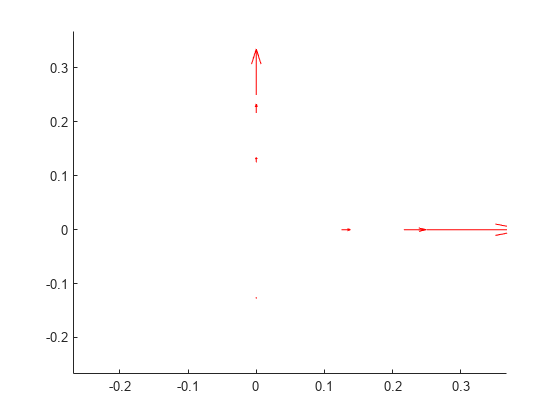


% Move the sensor, compute new received power and plot received power
% intensity
Emitters = newEmitters(n_Emitters,Pt,Pt,m);
Emitters(1).HTM = Em_Base_HTM*Trans3(1.5,0,0);
Emitters(2).HTM = Em_Base_HTM*Trans3(0.5,0,5);

PDSensor = vlpMoveSensor(PDSensor,Trans3(0,3,0));

A = Receiver2A(PDSensor);
B = Emitter2B(Emitters);
F = EmitRec2F(Emitters, PDSensor);

% Plot with received power intensity
figure(42)
PlotHTMArray(Emitters);
hx = PlotHTMArrayPr(PDSensor,k);
view(3)
axis 'equal'
axis([-0.5 3.5 -0.5 3.5 0 2])
grid on
view([-43.35 53.33]);

for lane = 1:16
    if (lane == 1)
    else
        PDSensor = vlpMoveSensor(PDSensor,Trans3(0,-0.2,0));
    end
    for position=1:16
        if (position == 1)
            
        elseif (mod(lane,2))
            PDSensor = vlpMoveSensor(PDSensor,Trans3(0.2,0,0));
        else 
            PDSensor = vlpMoveSensor(PDSensor,Trans3(-0.2,0,0));
        end
        % Recompute the F matrix
        F = EmitRec2F(Emitters, PDSensor);
        
        % Compute received power
        Pt_v = [Emitters.Pb]';
        Pr = A*F*B*Pt_v;
    
        % Get the new max valuefor scaling the received power plot
        MaxPr = max(Pr);
    
        % Update the PDSensor received power
        for i=1:numel(PDSensor)
            PDSensor(i).Pr = Pr(i);
            position_number = lane * position;
            myArray(position_number, 5 * 12 + i) = Pr(i);
        end

        pause(.1)
        figure(312)
        delete(hx)
        % Plot the receiver power intensities, scaled
        hx = PlotHTMArrayPr(PDSensor,k*MaxPr/MaxPr0);
    
    end
end

## Animate plot (Light Emitter 6)

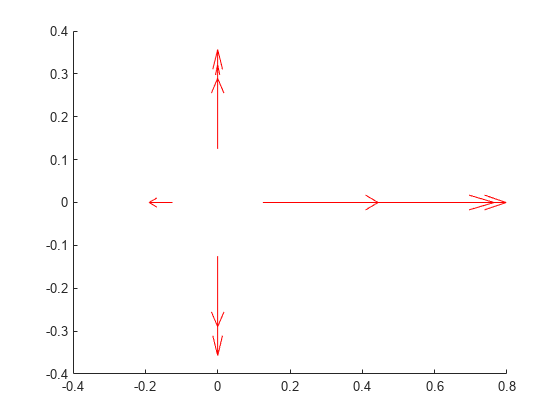


% Move the sensor, compute new received power and plot received power
% intensity
Emitters = newEmitters(n_Emitters,Pt,Pt,m);
Emitters(1).HTM = Em_Base_HTM*RotZ3(pi/2)*Trans3(1.5,0,0);
Emitters(2).HTM = Em_Base_HTM*Trans3(0.5,0,5);

PDSensor = vlpMoveSensor(PDSensor,Trans3(0,3,0));

A = Receiver2A(PDSensor);
B = Emitter2B(Emitters);
F = EmitRec2F(Emitters, PDSensor);

% Plot with received power intensity
figure(42)
PlotHTMArray(Emitters);
hx = PlotHTMArrayPr(PDSensor,k);
view(3)
axis 'equal'
axis([-0.5 3.5 -0.5 3.5 0 2])
grid on
view([-43.35 53.33]);

for lane = 1:16
    if (lane == 1)
    else
        PDSensor = vlpMoveSensor(PDSensor,Trans3(0,-0.2,0));
    end
    for position=1:16
        if (position == 1)
            
        elseif (mod(lane,2))
            PDSensor = vlpMoveSensor(PDSensor,Trans3(0.2,0,0));
        else 
            PDSensor = vlpMoveSensor(PDSensor,Trans3(-0.2,0,0));
        end
        % Recompute the F matrix
        F = EmitRec2F(Emitters, PDSensor);
        
        % Compute received power
        Pt_v = [Emitters.Pb]';
        Pr = A*F*B*Pt_v;
    
        % Get the new max valuefor scaling the received power plot
        MaxPr = max(Pr);
    
        % Update the PDSensor received power
        for i=1:numel(PDSensor)
            PDSensor(i).Pr = Pr(i);
            position_number = lane * position;
            myArray(position_number, 6 * 12 + i) = Pr(i);
        end

        pause(.1)
        figure(292)
        delete(hx)
        % Plot the receiver power intensities, scaled
        hx = PlotHTMArrayPr(PDSensor,k*MaxPr/MaxPr0);
    
    end
end

## Animate plot (Light Emitter 7)

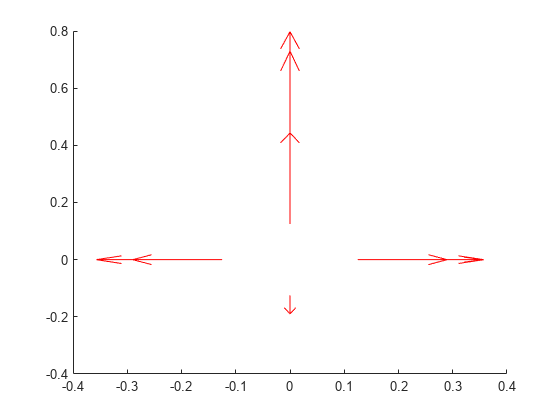


% Move the sensor, compute new received power and plot received power
% intensity
Emitters = newEmitters(n_Emitters,Pt,Pt,m);
Emitters(1).HTM = Em_Base_HTM*RotZ3(pi)*Trans3(1.5,0,0);
Emitters(2).HTM = Em_Base_HTM*Trans3(0.5,0,5);

PDSensor = vlpMoveSensor(PDSensor,Trans3(0,3,0));

A = Receiver2A(PDSensor);
B = Emitter2B(Emitters);
F = EmitRec2F(Emitters, PDSensor);

% Plot with received power intensity
figure(42)
PlotHTMArray(Emitters);
hx = PlotHTMArrayPr(PDSensor,k);
view(3)
axis 'equal'
axis([-0.5 3.5 -0.5 3.5 0 2])
grid on
view([-43.35 53.33]);

for lane = 1:16
    if (lane == 1)
    else
        PDSensor = vlpMoveSensor(PDSensor,Trans3(0,-0.2,0));
    end
    for position=1:16
        if (position == 1)
            
        elseif (mod(lane,2))
            PDSensor = vlpMoveSensor(PDSensor,Trans3(0.2,0,0));
        else 
            PDSensor = vlpMoveSensor(PDSensor,Trans3(-0.2,0,0));
        end
        % Recompute the F matrix
        F = EmitRec2F(Emitters, PDSensor);
        
        % Compute received power
        Pt_v = [Emitters.Pb]';
        Pr = A*F*B*Pt_v;
    
        % Get the new max valuefor scaling the received power plot
        MaxPr = max(Pr);
    
        % Update the PDSensor received power
        for i=1:numel(PDSensor)
            PDSensor(i).Pr = Pr(i);
            position_number = lane * position;
            myArray(position_number, 7 * 12 + i) = Pr(i);
        end

        pause(.1)
        figure(252)
        delete(hx)
        % Plot the receiver power intensities, scaled
        hx = PlotHTMArrayPr(PDSensor,k*MaxPr/MaxPr0);
    
    end
end

## Animate plot (Light Emitter 8)

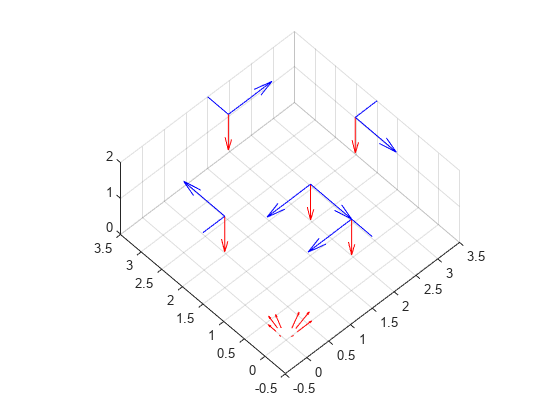

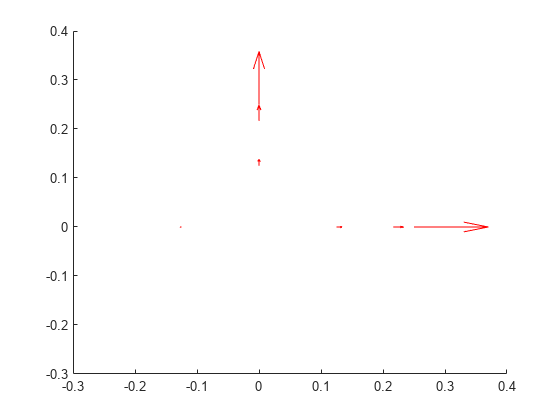


% Move the sensor, compute new received power and plot received power
% intensity
Emitters = newEmitters(n_Emitters,Pt,Pt,m);
Emitters(1).HTM = Em_Base_HTM*RotZ3(3*pi/2)*Trans3(1.5,0,0);
Emitters(2).HTM = Em_Base_HTM*Trans3(0.5,0,5);

PDSensor = vlpMoveSensor(PDSensor,Trans3(0,3,0));

A = Receiver2A(PDSensor);
B = Emitter2B(Emitters);
F = EmitRec2F(Emitters, PDSensor);

% Plot with received power intensity
figure(42)
PlotHTMArray(Emitters);
hx = PlotHTMArrayPr(PDSensor,k);
view(3)
axis 'equal'
axis([-0.5 3.5 -0.5 3.5 0 2])
grid on
view([-43.35 53.33]);

for lane = 1:16
    if (lane == 1)
    else
        PDSensor = vlpMoveSensor(PDSensor,Trans3(0,-0.2,0));
    end
    for position=1:16
        if (position == 1)
            
        elseif (mod(lane,2))
            PDSensor = vlpMoveSensor(PDSensor,Trans3(0.2,0,0));
        else 
            PDSensor = vlpMoveSensor(PDSensor,Trans3(-0.2,0,0));
        end
        % Recompute the F matrix
        F = EmitRec2F(Emitters, PDSensor);
        
        % Compute received power
        Pt_v = [Emitters.Pb]';
        Pr = A*F*B*Pt_v;
    
        % Get the new max valuefor scaling the received power plot
        MaxPr = max(Pr);
    
        % Update the PDSensor received power
        for i=1:numel(PDSensor)
            PDSensor(i).Pr = Pr(i);
            position_number = lane * position;
            myArray(position_number, 8 * 12 + i) = Pr(i);
        end

        pause(.1)
        figure(232)
        delete(hx)
        % Plot the receiver power intensities, scaled
        hx = PlotHTMArrayPr(PDSensor,k*MaxPr/MaxPr0);
    
    end
end

## Write Matrix to .csv File


writematrix(myArray, 'myData.csv');